# Offline RL for GBWM — Week 4 v2: Macro-Augmented State

Single change vs week4_baseline_realdata: extend state from 2D to 6D by appending 4 z-scored FRED macro factors (DGS10, T10Y2Y, VIXCLS, DFF). Standardization uses TRAIN-segment mean/std only (no look-ahead). Everything else (data, episode generation, agent, training, eval windows) mirrors the baseline so the comparison is clean A/B.

Technical debt fixes carried over: - fileDatastore restricted to loggedData*.mat - yline calls hide from legend - eval reports P10/P90 percentiles + action diversity

clear; clc;
rng(1000, "twister");

## Parameter Settings

initialWealth   = 100000;
goalWealth      = 102000;
contribution    = 0;
rebalanceStep   = calmonths(1);

trainingRange   = 2000;
horizonPeriods  = 30;
numEpisodes     = 130;
numActions      = 15;

logsFolder      = fullfile("experiments", "logs", "week4_macro_state");

hiddenUnits     = 32;
maxEpochs       = 100;
stepsPerEpoch   = 400;
miniBatchSize   = 256;
discountFactor  = 0.995;

## Load price data

pricesTT   = readtable("data/prices_train.csv");
assetNames = pricesTT.Properties.VariableNames(2:end);
P_train    = pricesTT{:, 2:end};
R_train    = diff(log(P_train));

R_sub = R_train(1:trainingRange, :);
mu    = mean(R_sub, 1)';
Sigma = cov(R_sub);

p = Portfolio("AssetList", assetNames);
p = setDefaultConstraints(p);
p = setAssetMoments(p, mu, Sigma);
W_frontier = estimateFrontier(p, numActions);

## Load macro data and fit z-score on train only

macroTT   = readtable("data/macro_train.csv");
macroNames = macroTT.Properties.VariableNames(2:end);
M_train   = macroTT{:, 2:end};

% Standardization parameters from TRAIN segment only (no look-ahead)
macroMean = mean(M_train, 1);
macroStd  = std(M_train, 0, 1);
macroStd(macroStd == 0) = 1;          % guard against degenerate columns

M_train_z = (M_train - macroMean) ./ macroStd;

fprintf("Macro factors: %s\n", strjoin(macroNames, ", "));

Macro factors: DGS10, T10Y2Y, VIXCLS, DFF


fprintf("Train means: %s\n", mat2str(macroMean, 4));

Train means: [2.404 1.443 16.86 0.614]


fprintf("Train stds : %s\n", mat2str(macroStd, 4));

Train stds : [0.5532 0.806 5.632 0.7588]


## Build offline episodes — state now 6D

if ~isfolder(logsFolder); mkdir(logsFolder); end

normalizeWealth = @(w) min(w/goalWealth, 5);
timeFrac        = @(t) t / horizonPeriods;

obsDim = 2 + size(M_train_z, 2);   % 2 + 4 = 6

episodeCount = 0;
startIdx     = 1;
stepSize     = floor(horizonPeriods/2);

while episodeCount < numEpisodes && (startIdx + horizonPeriods - 1) <= size(R_sub,1)
    episodeCount = episodeCount + 1;
    expStruct = repmat(struct("Observation",[],"Action",[],"Reward",[], ...
        "NextObservation",[],"IsDone",[]), horizonPeriods, 1);

    wealth = initialWealth;
    for t = 1:horizonPeriods
        dayIdx   = startIdx + t - 1;
        macroVec = M_train_z(dayIdx, :)';
        obs      = [normalizeWealth(wealth); timeFrac(t); macroVec];

        aIdx = randi(numActions);
        w    = W_frontier(:, aIdx);

        r_tp1      = R_sub(dayIdx, :) * w;
        wealthNext = (wealth + contribution) * (1 + r_tp1);

        reward = log(wealthNext / wealth);
        if t == horizonPeriods && wealthNext >= goalWealth
            reward = reward + 1.0;
        end

        nextDayIdx   = min(dayIdx + 1, size(M_train_z, 1));
        nextMacroVec = M_train_z(nextDayIdx, :)';
        nextObs      = [normalizeWealth(wealthNext); ...
                        timeFrac(min(t+1, horizonPeriods)); ...
                        nextMacroVec];
        isDone       = (t == horizonPeriods);

        expStruct(t).Observation     = {obs};
        expStruct(t).Action          = {aIdx};
        expStruct(t).Reward          = reward;
        expStruct(t).NextObservation = {nextObs};
        expStruct(t).IsDone          = isDone;

        wealth = wealthNext;
    end

    epFile = fullfile(logsFolder, sprintf("loggedData%03d.mat", episodeCount));
    exp = expStruct;
    save(epFile, "exp");
    startIdx = startIdx + stepSize;
end

fprintf("Saved %d episodes (%d steps each), %d total transitions.\n", ...
    episodeCount, horizonPeriods, episodeCount * horizonPeriods);

Saved 130 episodes (30 steps each), 3900 total transitions.


## FileDatastore — restricted to loggedData*.mat (avoid TrainedAgent.mat pollution)

myReadFcn = @(fname) load(fname, "exp").exp;
fds = fileDatastore(fullfile(logsFolder, "loggedData*.mat"), "ReadFcn", myReadFcn);

## Build DQN agent (only obsDim and input layer change)

obsInfo = rlNumericSpec([obsDim 1], Name="GBWMObservation");
actInfo = rlFiniteSetSpec(1:numActions, Name="AllocationIndex");

criticLG = layerGraph([
    featureInputLayer(obsInfo.Dimension(1), Name="state")
    fullyConnectedLayer(hiddenUnits)
    reluLayer
    fullyConnectedLayer(hiddenUnits)
    reluLayer
    fullyConnectedLayer(numActions, Name="Qout")
    ]);

criticNet = dlnetwork(criticLG);
critic    = rlVectorQValueFunction(criticNet, obsInfo, actInfo);

agentOpts = rlDQNAgentOptions( ...
    DiscountFactor=discountFactor, ...
    ExperienceBufferLength=1e6, ...
    MiniBatchSize=miniBatchSize, ...
    TargetUpdateMethod="periodic", ...
    TargetUpdateFrequency=4, ...
    UseDoubleDQN=true);
agentOpts.CriticOptimizerOptions.LearnRate         = 5e-4;
agentOpts.CriticOptimizerOptions.GradientThreshold = 1;
agent = rlDQNAgent(critic, agentOpts);

## Train offline

tfdOpts = rlTrainingFromDataOptions( ...
    MaxEpochs        = maxEpochs, ...
    NumStepsPerEpoch = stepsPerEpoch, ...
    Plots            = "training-progress", ...
    Verbose          = true);
tfdStats = trainFromData(agent, fds, tfdOpts);

Epoch:    1/ 100 | Step Count:    400/40000 | Q Value:   1.9277 | Num experiences added: 3900
Epoch:    2/ 100 | Step Count:    800/40000 | Q Value:   1.8422 | Num experiences added:    0
Epoch:    3/ 100 | Step Count:   1200/40000 | Q Value:   1.0270 | Num experiences added:    0
Epoch:    4/ 100 | Step Count:   1600/40000 | Q Value:   0.9670 | Num experiences added:    0
Epoch:    5/ 100 | Step Count:   2000/40000 | Q Value:   0.9216 | Num experiences added:    0
Epoch:    6/ 100 | Step Count:   2400/40000 | Q Value:   0.8921 | Num experiences added:    0
Epoch:    7/ 100 | Step Count:   2800/40000 | Q Value:   0.8545 | Num experiences added:    0
Epoch:    8/ 100 | Step Count:   3200/40000 | Q Value:   0.7978 | Num experiences added:    0
Epoch:    9/ 100 | Step Count:   3600/40000 | Q Value:   0.7553 | Num experiences added:    0
Epoch:   10/ 100 | Step Count:   4000/40000 | Q Value:   0.6932 | Num experiences added:    0
Epoch:   11/ 100 | Step Count:   4400/40000 | Q Value:   0.6

save(fullfile(logsFolder, "TrainedAgent.mat"), "agent");

## Multi-window hold-out evaluation

[R_full, M_test_z] = inputTestData('data/prices_test.csv', 'data/macro_test.csv', ...
                                    macroMean, macroStd);

numEvalEpisodes = 30;
evalStepSize    = 30;   % keep parity with baseline (30 windows × 30 steps = 900 days)
successCount    = 0;
allSharpes      = nan(numEvalEpisodes, 1);
allMaxDD        = nan(numEvalEpisodes, 1);
allTermWealth   = nan(numEvalEpisodes, 1);
allWealthPaths  = cell(numEvalEpisodes, 1);
allActions      = zeros(numEvalEpisodes, horizonPeriods);

fprintf("\n=== Multi-window hold-out evaluation ===\n");


=== Multi-window hold-out evaluation ===


for ep = 1:numEvalEpisodes
    startEval = (ep-1)*evalStepSize + 1;
    if startEval + horizonPeriods - 1 > size(R_full, 1)
        fprintf("Ep %d: skipped (insufficient data)\n", ep);
        break;
    end

    wealth = zeros(horizonPeriods+1, 1);
    wealth(1) = initialWealth;
    chosenActions = zeros(1, horizonPeriods);
    for t = 1:horizonPeriods
        dayIdx   = startEval + t - 1;
        macroVec = M_test_z(dayIdx, :)';
        obs      = { [normalizeWealth(wealth(t)); timeFrac(t); macroVec] };
        aGreedy  = agent.getAction(obs);
        chosenActions(t) = aGreedy{1};
        w        = W_frontier(:, aGreedy{1});
        r_tp1    = R_full(dayIdx, :) * w;
        wealth(t+1) = (wealth(t) + contribution) * (1 + r_tp1);
    end

    rets    = diff(log(wealth));
    sharpe  = mean(rets) / std(rets) * sqrt(252);
    maxDD   = max(cummax(wealth) - wealth) / max(wealth);
    success = (wealth(end) >= goalWealth);

    allSharpes(ep)     = sharpe;
    allMaxDD(ep)       = maxDD;
    allTermWealth(ep)  = wealth(end);
    allWealthPaths{ep} = wealth;
    allActions(ep, :)  = chosenActions;
    successCount       = successCount + double(success);

    fprintf("Ep %d: terminal=%.0f, success=%d, Sharpe=%.2f, MaxDD=%.2f%%\n", ...
        ep, wealth(end), success, sharpe, maxDD*100);
    fprintf("  actions: %s\n", mat2str(chosenActions));
end

Ep 1: terminal=83921, success=0, Sharpe=-3.14, MaxDD=23.07%


  actions: [15 15 15 15 15 15 15 15 15 15 15 15 13 13 13 13 13 13 13 13 7 14 14 14 14 14 14 14 14 14]


Ep 2: terminal=90116, success=0, Sharpe=-1.63, MaxDD=21.66%


  actions: [15 15 15 15 15 15 15 15 15 15 15 15 15 13 13 13 13 13 7 7 14 14 14 14 14 14 14 14 14 14]


Ep 3: terminal=59346, success=0, Sharpe=-7.80, MaxDD=40.65%


  actions: [15 15 15 15 15 15 15 15 15 15 15 15 15 15 15 14 14 14 14 14 14 14 14 14 14 14 14 14 14 14]


Ep 4: terminal=106714, success=1, Sharpe=0.89, MaxDD=17.40%


  actions: [15 15 15 15 15 15 15 15 15 15 15 15 15 15 15 15 15 15 15 15 7 7 7 7 7 14 14 14 14 14]


Ep 5: terminal=103832, success=1, Sharpe=0.62, MaxDD=12.62%


  actions: [15 15 15 15 15 15 15 15 15 15 15 15 15 15 15 15 15 15 15 15 15 15 15 15 15 15 15 15 14 14]


Ep 6: terminal=91665, success=0, Sharpe=-2.04, MaxDD=18.21%


  actions: [15 15 15 15 15 15 15 15 15 10 10 10 10 10 10 10 10 10 7 7 7 7 7 7 7 14 14 14 14 14]


Ep 7: terminal=98956, success=0, Sharpe=-0.46, MaxDD=4.93%


  actions: [10 10 10 10 10 10 10 10 10 10 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7]


Ep 8: terminal=105204, success=1, Sharpe=2.01, MaxDD=1.99%


  actions: [7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7]


Ep 9: terminal=100685, success=0, Sharpe=0.40, MaxDD=5.68%


  actions: [10 10 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7]


Ep 10: terminal=98715, success=0, Sharpe=-0.79, MaxDD=4.74%


  actions: [7 10 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7]


Ep 11: terminal=105447, success=1, Sharpe=3.82, MaxDD=2.79%


  actions: [10 10 10 10 7 7 10 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7]


Ep 12: terminal=102537, success=1, Sharpe=1.84, MaxDD=2.48%


  actions: [7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7]


Ep 13: terminal=104028, success=1, Sharpe=2.98, MaxDD=2.73%


  actions: [7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7]


Ep 14: terminal=95128, success=0, Sharpe=-4.21, MaxDD=5.36%


  actions: [7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7]


Ep 15: terminal=97855, success=0, Sharpe=-1.67, MaxDD=3.79%


  actions: [7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7]


Ep 16: terminal=106808, success=1, Sharpe=4.98, MaxDD=1.98%


  actions: [7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7]


Ep 17: terminal=101222, success=0, Sharpe=1.07, MaxDD=1.88%


  actions: [7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7]


Ep 18: terminal=101524, success=0, Sharpe=1.23, MaxDD=1.83%


  actions: [7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7]


Ep 19: terminal=95449, success=0, Sharpe=-3.67, MaxDD=5.48%


  actions: [7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7]


Ep 20: terminal=107121, success=1, Sharpe=6.29, MaxDD=1.11%


  actions: [7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7]


Ep 21: terminal=103313, success=1, Sharpe=2.51, MaxDD=2.23%


  actions: [7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7]


Ep 22: terminal=107435, success=1, Sharpe=3.89, MaxDD=3.72%


  actions: [7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7]


Ep 23: terminal=100450, success=0, Sharpe=0.59, MaxDD=2.06%


  actions: [7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7]


Ep 24: terminal=100151, success=0, Sharpe=0.10, MaxDD=3.05%


  actions: [7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7]


Ep 25: terminal=95708, success=0, Sharpe=-2.80, MaxDD=8.58%


  actions: [7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7]


Ep 26: terminal=101182, success=0, Sharpe=0.81, MaxDD=2.17%


  actions: [7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7]


Ep 27: terminal=98472, success=0, Sharpe=-0.98, MaxDD=5.40%


  actions: [7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7]


Ep 28: terminal=92875, success=0, Sharpe=-1.74, MaxDD=11.44%


  actions: [7 7 7 7 7 7 10 10 10 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7]


Ep 29: terminal=95881, success=0, Sharpe=-1.48, MaxDD=8.22%


  actions: [7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7]


Ep 30: terminal=96512, success=0, Sharpe=-2.03, MaxDD=8.31%


  actions: [7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7 7]


## Summary — pivot to risk-adjusted metrics

fprintf("\n--- Summary ---\n");


--- Summary ---


fprintf("Success rate         : %d / %d\n", successCount, numEvalEpisodes);

Success rate         : 10 / 30


fprintf("Mean Sharpe          : %.2f (std %.2f)\n", ...
    mean(allSharpes,'omitnan'), std(allSharpes,'omitnan'));

Mean Sharpe          : -0.01 (std 2.95)


fprintf("Mean MaxDD           : %.2f%% (std %.2f%%)\n", ...
    mean(allMaxDD,'omitnan')*100, std(allMaxDD,'omitnan')*100);

Mean MaxDD           : 7.85% (std 8.70%)


fprintf("Mean Terminal Wealth : %.0f\n", mean(allTermWealth,'omitnan'));

Mean Terminal Wealth : 98275



fprintf("\n--- Risk-adjusted breakdown ---\n");


--- Risk-adjusted breakdown ---


fprintf("Terminal wealth P10 / P50 / P90 : %.0f / %.0f / %.0f\n", ...
    prctile(allTermWealth,10), prctile(allTermWealth,50), prctile(allTermWealth,90));

Terminal wealth P10 / P50 / P90 : 90890 / 100300 / 106761


fprintf("Sharpe       min / med / max   : %.2f / %.2f / %.2f\n", ...
    min(allSharpes), median(allSharpes,'omitnan'), max(allSharpes));

Sharpe       min / med / max   : -7.80 / 0.25 / 6.29


fprintf("MaxDD P50 / P90               : %.2f%% / %.2f%%\n", ...
    prctile(allMaxDD,50)*100, prctile(allMaxDD,90)*100);

MaxDD P50 / P90               : 4.83% / 19.93%



% Action diversity
flatActions = allActions(:);
uniqA = unique(flatActions);
fprintf("\nActions chosen across all eval steps: %s\n", mat2str(uniqA'));


Actions chosen across all eval steps: [7 10 13 14 15]


for a = uniqA'
    fprintf("  action %2d : %d times (%.1f%%)\n", a, sum(flatActions==a), ...
        100*sum(flatActions==a)/numel(flatActions));
end

  action  7 : 714 times (79.3%)
  action 10 : 30 times (3.3%)
  action 13 : 13 times (1.4%)
  action 14 : 46 times (5.1%)
  action 15 : 97 times (10.8%)


## Plot wealth paths — percentile band style

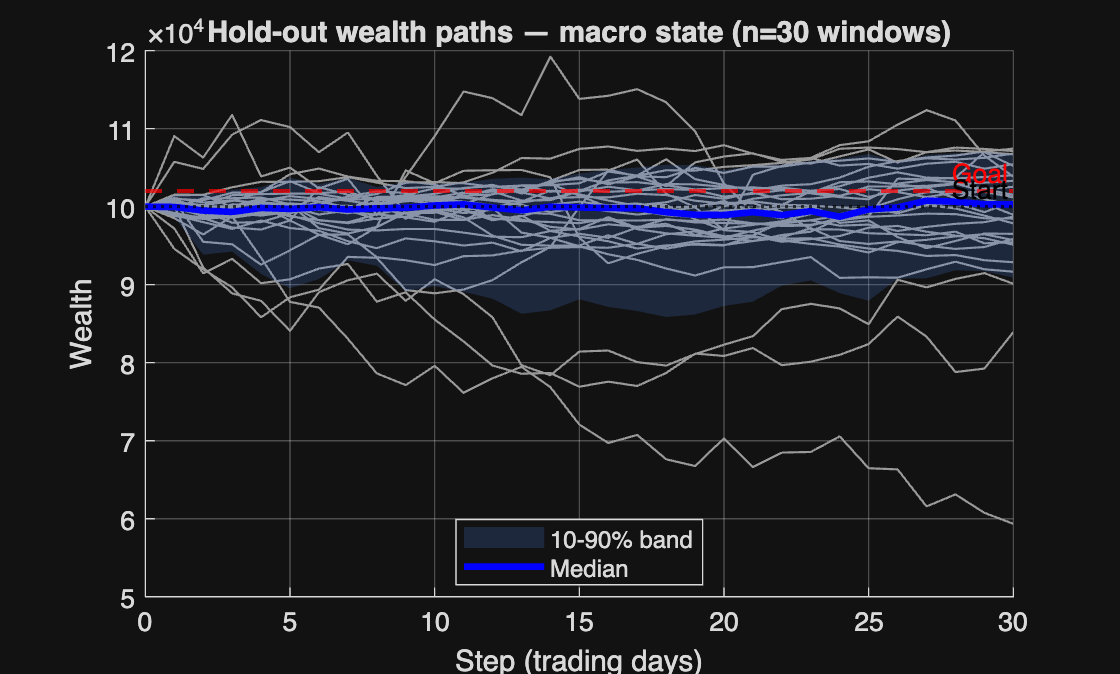

figure('Name','Hold-out wealth paths');
hold on;

allW = nan(numEvalEpisodes, horizonPeriods+1);
for ep = 1:numEvalEpisodes
    if ~isempty(allWealthPaths{ep})
        allW(ep, :) = allWealthPaths{ep}';
    end
end

steps = 0:horizonPeriods;

for ep = 1:numEvalEpisodes
    plot(steps, allW(ep,:), 'Color', [0.6 0.6 0.6 0.3], 'LineWidth', 0.8, ...
        'HandleVisibility', 'off');
end

p10 = prctile(allW, 10, 1);
p90 = prctile(allW, 90, 1);
fill([steps, fliplr(steps)], [p10, fliplr(p90)], [0.3 0.5 0.9], ...
    'FaceAlpha', 0.2, 'EdgeColor', 'none', 'DisplayName', '10-90% band');

plot(steps, median(allW, 1, 'omitnan'), 'b-', 'LineWidth', 2.5, ...
    'DisplayName', 'Median');

yline(goalWealth, '--r', 'Goal', 'LineWidth', 1.5, 'HandleVisibility', 'off');
yline(initialWealth, ':k', 'Start', 'LineWidth', 1.2, 'HandleVisibility', 'off');

xlabel('Step (trading days)');
ylabel('Wealth');
title(sprintf('Hold-out wealth paths — macro state (n=%d windows)', numEvalEpisodes));
legend('Location','best');
grid on;

## Local Functions

function [R, M_z] = inputTestData(priceFile, macroFile, macroMean, macroStd)
    pricesTT = readtable(priceFile, 'VariableNamingRule', 'preserve');
    P = pricesTT{:, 2:end};
    R = diff(log(P));

    macroTT = readtable(macroFile, 'VariableNamingRule', 'preserve');
    M = macroTT{:, 2:end};
    M_z = (M - macroMean) ./ macroStd;   % standardize with TRAIN params
end